## Notch Filter implementation of the ECG signal filter

#### Import signal and plot the first second

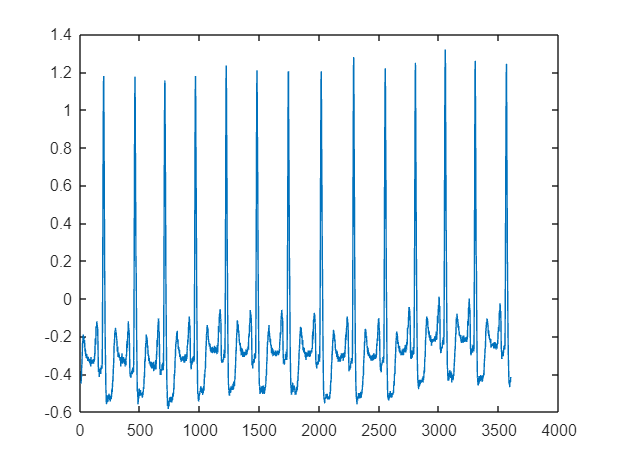

[sig, Fs, tm] = rdsamp('mitdb/105', 1);
signal = sig(1:3600);
%signal = signal - mean(signal);
plot(signal);

#### **Obtain Fourier Transform**

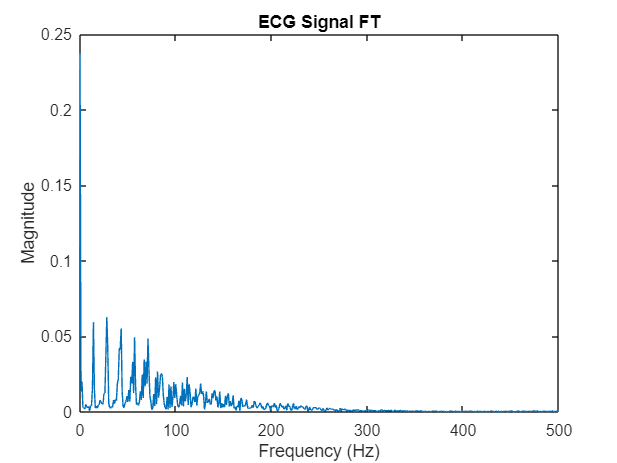

N = 3600;
T = 1/Fs;
%plot the fourier transform of the signal
%sig_zero_mean = ss; - mean(ss); %subtract mean value from signal to address large DC component
sig_fft = fft(signal);
%f = (0:length(freq_domain_signal)-1)*Fs/length(freq_domain_signal);
sig_fft_magnitude = abs(fftshift(sig_fft)) / N;    % Magnitude of the FFT
frequencies = (-N/2:N/2-1);      % Frequency axis

figure
plot(frequencies, sig_fft_magnitude);
title('ECG Signal FT')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
xlim([0,500])

Generate noise signal

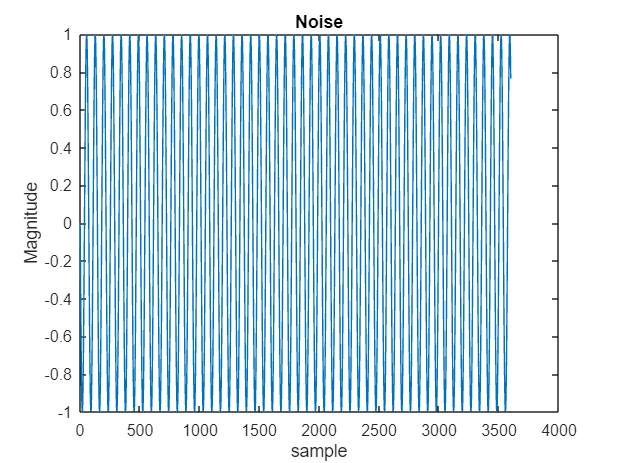


noise_t = linspace(1,T,N);
noise = 1*sin(2*pi*50*noise_t); 
figure
plot(noise)
xlabel('sample')
ylabel('Magnitude')
title('Noise')

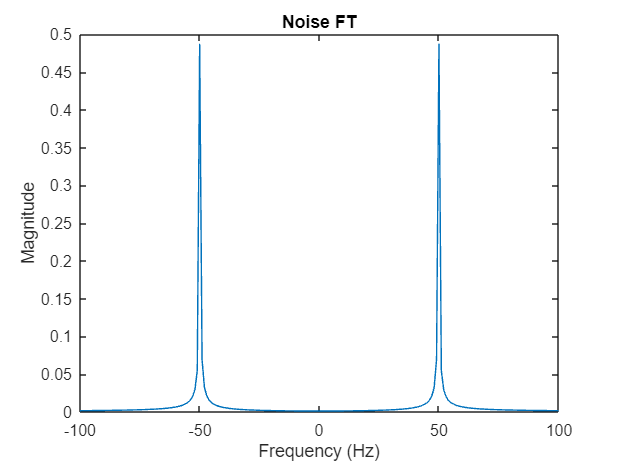



% Compute the FFT
noise_fft = fft(noise);               % Perform the FFT
noise_fft_magnitude = abs(fftshift(noise_fft)) / N;    % Magnitude of the FFT
figure
plot(frequencies, noise_fft_magnitude);
title('Noise FT')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
xlim([-100,100])

Add noise to the original signal

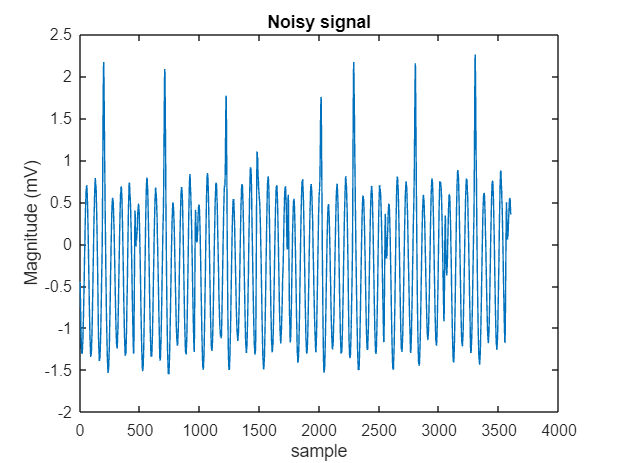

noisy_signal = signal+transpose(noise);
%noisy_signal = noisy_signal(:,1);
figure
plot(noisy_signal)
xlabel('sample')
ylabel('Magnitude (mV)')
title('Noisy signal')

Find FFT of noisy signal

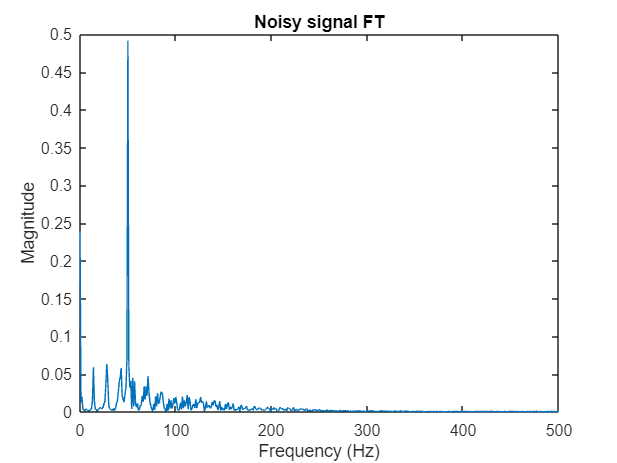

noisy_signal_fft = fft(noisy_signal);               % Perform the FFT
noisy_signal_fft_magnitude = abs(fftshift(noisy_signal_fft)) / N;    % Magnitude of the FFT
figure
plot(frequencies, noisy_signal_fft_magnitude);
title('Noisy signal FT')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
xlim([0,500])

Now, obtain notch filter

% % Design IIR notch filter
% wo = 50 / (Fs/2);    % Normalized frequency (center at 50 Hz)
% bw = wo /35;         % Bandwidth (adjust as needed)
% %[b, a] = butter(50,[wo-0.1 wo+0.1],"stop"); % Design notch filter
% [b, a] = iirnotch(wo,bw); 
% [h,w] = freqz(b, a, 1000, Fs);
% figure;
% plot(w, abs(h));
% title('Frequency Response of Notch Filter');
% xlabel('Frequency (Hz)');
% ylabel('Magnitude');

apply filter

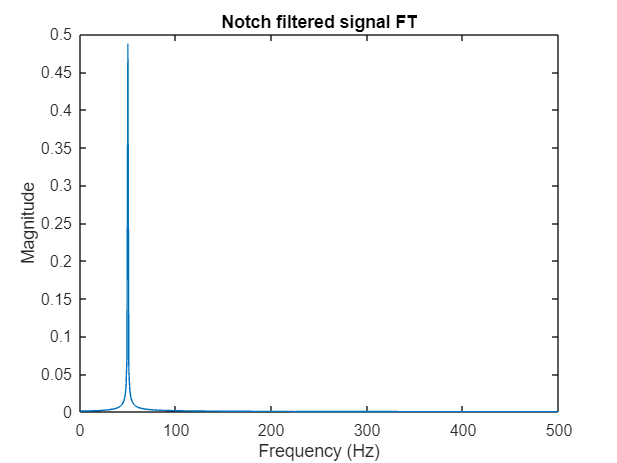

notch_filtered_sig =  filter(Hd,noisy_signal);
notch_filtered_fft = fft(notch_filtered_sig);               % Perform the FFT
notch_filtered_fft_magnitude = abs(fftshift(notch_filtered_fft)) / N; 
figure
plot(frequencies, notch_filtered_fft_magnitude);
title('Notch filtered signal FT')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
xlim([0,500])